close all;
clear all;

c_p_nom = 1.0;
c_v_nom = 1.0;
c_p_min = c_p_nom - 0.1;
c_p_max = c_p_nom + 0.1;
c_v_min = c_v_nom - 0.075;
c_v_max = c_v_nom + 0.075;

m = 1.0;

% uncertain plant and vars
c_p = ureal('c_p', c_p_nom, 'Range', [c_p_min, c_p_max]);
c_v = ureal('c_v', c_v_nom, 'Range', [c_v_min, c_v_max]);
uA = [0, 1; -c_p/m, -c_v/m];
uB = [0; c_p/m];
uC = [1, 0];
uD = 0;
G_unc = ss(uA,uB,uC,uD); 

% nominal plant
nA = [0, 1; -c_p_nom/m, -c_v_nom/m];
nB = [0; c_p_nom/m];
nC = [1, 0];
nD = 0;
G_nom = ss(nA,nB,nC,nD);

% sample uncertain plant
Nsamples = 50;
rng(1234);
G_samples = usample(G_unc, Nsamples);

omegavals = logspace(-1, 2, 200);
Delta_mag = zeros(size(omegavals));

for i = 1:length(omegavals)
    % calc G_nom and all G_samples at j*omega(i)
    G_nom_val = freqresp(G_nom, omegavals(i));
    G_diff_vals = zeros(1, Nsamples);
    for k = 1:Nsamples
        G_diff_vals(k) = abs(freqresp(G_samples(:,:,k), omegavals(i)) - G_nom_val);
    end
    Delta_mag(i) = max(G_diff_vals);
end

% maximum magnitude difference across all samples
Delta_mag;  % bound b(omega)


syms s m c_p Delta_p c_v Delta_v omega

den1 = m * s^2 + (c_v + Delta_v) * s + (c_p + Delta_p);
den2 = m * s^2 + c_v * s + c_p;

Delta = (c_p + Delta_p) / den1 - c_p / den2;

Delta_expanded = expand(Delta);
Delta_collected = collect(Delta_expanded, [s, Delta_p, Delta_v]);

numer = (c_p + Delta_p) * den2 - c_p * den1;
denom = den1 * den2;
Delta_combined = numer / denom;

Delta_simplified = simplify(Delta_combined)

$$Delta\_simplified = \frac{s\,\left(\Delta_{p}\,c_{v}-\Delta_{v}\,c_{p}+\Delta_{p}\,m\,s\right)}{\left(m\,s^{2}+c_{v}\,s+c_{p}\right)\,\left(\Delta_{p}+c_{p}+\Delta_{v}\,s+c_{v}\,s+m\,s^{2}\right)}$$

b = subs(Delta_simplified, s, 1j * omega)

$$b = \frac{\omega \,\left(\Delta_{p}\,c_{v}-\Delta_{v}\,c_{p}+\Delta_{p}\,m\,\omega \,\mathrm{i}\right)\,\mathrm{i}}{\left(-m\,\omega^{2}+\mathrm{i}\,c_{v}\,\omega +c_{p}\right)\,\left(\Delta_{p}+c_{p}-m\,\omega^{2}+\Delta_{v}\,\omega \,\mathrm{i}+c_{v}\,\omega \,\mathrm{i}\right)}$$


params = struct('m', 1.0, 'c_p', 1.0, 'Delta_p', 0.1, 'c_v', 1.0, 'Delta_v', 0.075);
[num, den] = numden(subs(Delta_simplified, params))

$$num = s\,\left(4\,s+1\right)$$

$$den = \left(40\,s^{2}+43\,s+44\right)\,\left(s^{2}+s+1\right)$$

num_coeffs = sym2poly(num);
den_coeffs = sym2poly(den);

DeltaTF = tf(num_coeffs, den_coeffs);


figure;
hold on;
bodemag(DeltaTF, omegavals);
stf = tf('s')

stf =
 
  s
 
Continuous-time transfer function.
Model Properties


semilogx(omegavals, 20*log10(Delta_mag), 'r');

%bomega = DeltaTF * 3 * 
T = 1/1;
zeta = 0.3;
bs = 0.2 * stf/(T+stf) * 1 / (1 + 2*zeta*T*stf+stf^2*T^2) * tf(makeweight(2, 1, 0.8))

bs =
 
               0.16 s^2 + 0.1386 s
  ----------------------------------------------
  s^4 + 1.946 s^3 + 2.154 s^2 + 1.554 s + 0.3464
 
Continuous-time transfer function.
Model Properties



disp(tf2latex(bs, 3))

\\frac{0.139*s + 0.16*s^2}{1.55*s + 2.15*s^2 + 1.95*s^3 + s^4 + 0.346}


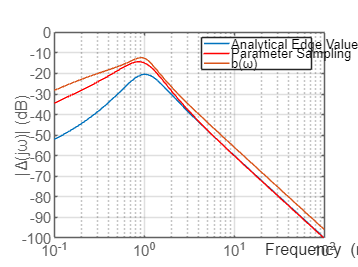


bodemag(bs, omegavals);
grid on;
hold off;
ylim([-100, 0])
legend("Analytical Edge Values", "Parameter Sampling", "b(ω)",  'Location',"best")
xlabel('Frequency')
ylabel('|Δ(jω)|')
print(gcf, 'figures/1_tight_bound.png', '-dpng', '-r300');


isstable(1/DeltaTF)

ans = logical
   0


isproper(1/DeltaTF)

ans = logical
   0
